clear
cd '~/Documents/Spatial/Project/'

data = readtable('Berkeley.csv');

# Part 1 - Preliminary Analysis (Some parts are in Python)

%Showing the kinds of crimes in the dataset that were given the 'violent' tag
data.OFFENSE(data.VIOLENT_FLG==1)

ans =     'GUN/WEAPON'
    'GUN/WEAPON'
    'ARSON'
    'GUN/WEAPON'
    'GUN/WEAPON'
    'GUN/WEAPON'
    'GUN/WEAPON'
    'ARSON'
    'GUN/WEAPON'
    'GUN/WEAPON'
    'ARSON'
    'GUN/WEAPON'
    'GUN/WEAPON'
    'GUN/WEAPON'
    'GUN/WEAPON'
    'GUN/WEAPON'
    'GUN/WEAPON'
    'ARSON'
    'ARSON'
    'ARSON'
    'GUN/WEAPON'
    'GUN/WEAPON'
    'ARSON'
    'GUN/WEAPON'
    'ARSON'
    'GUN/WEAPON'
    'GUN/WEAPON'
    'GUN/WEAPON'
    'ARSON'
    'ARSON'
    'HOMICIDE'
    'GUN/WEAPON'
    'GUN/WEAPON'
    'GUN/WEAPON'
    'HOMICIDE'
    'GUN/WEAPON'
    'GUN/WEAPON'
    'GUN/WEAPON'
    'ARSON'
    'ARSON'
    'GUN/WEAPON'
    'GUN/WEAPON'
    'GUN/WEAPON'
    'GUN/WEAPON'
    'ARSON'
    'GUN/WEAPON'


%Reading in the shapefile of Berkeley
[S, A] = shaperead('Census Block Polygons 2010/geo_export_9702b0bc-dfe0-42aa-bab9-e9ca83abd50f.shp','UseGeoCoords',true);

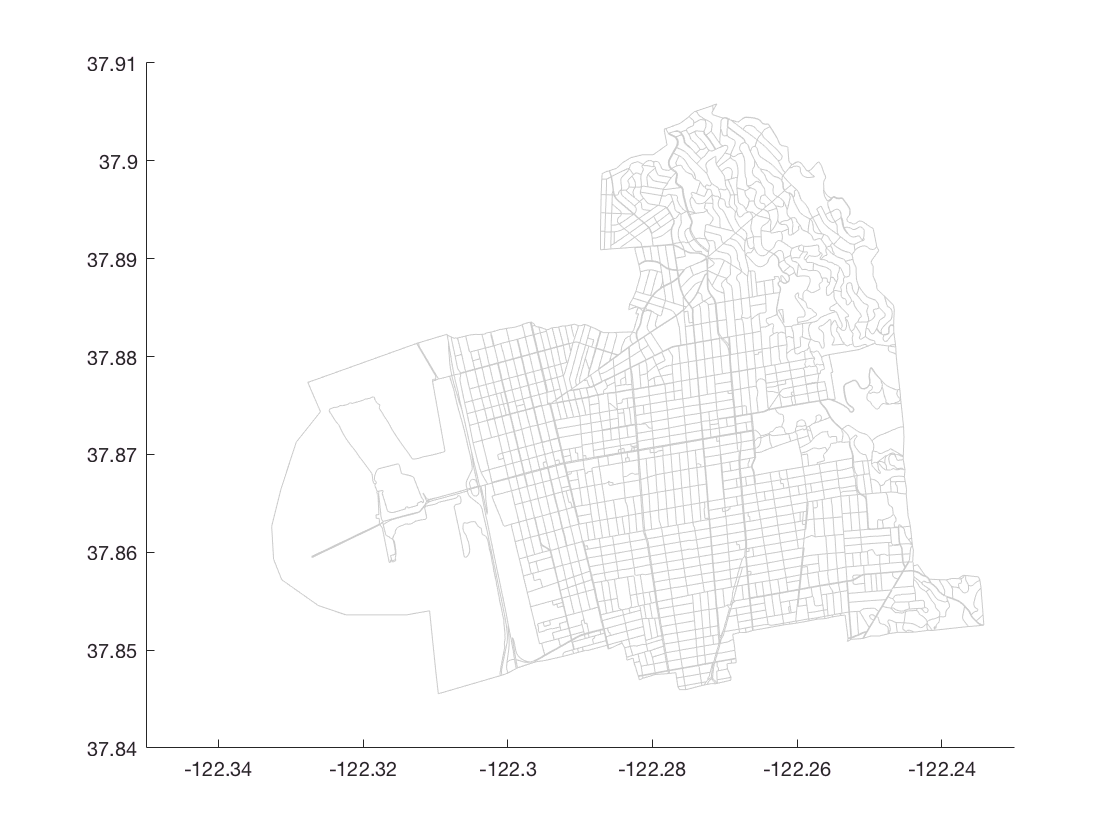

%Plotting the Berkeley shapefile
clf;
figure
hold on
for x=1:size(S)
    plot(S(x).Lon, S(x).Lat,'Color',[0.8,0.8,0.8]);
end
axis([-122.35 -122.23 37.84 37.91])
saveas(gcf,'Berkeley.png')

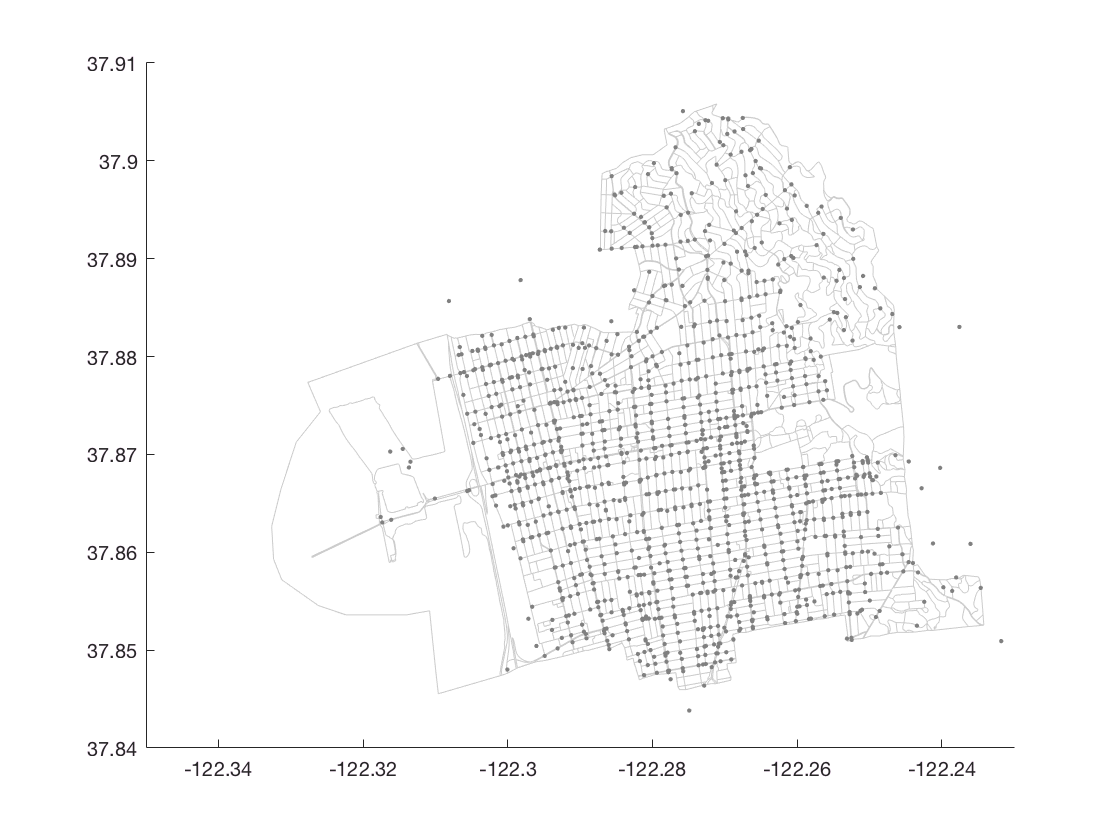

%Superimposing the Berkeley crimes onto the Berkeley shapefile
plot(data.Longitude, data.Latitude,'.','Color',[0.5,0.5,0.5],'MarkerSize',10)
saveas(gcf,'Berkeley crimes.png')

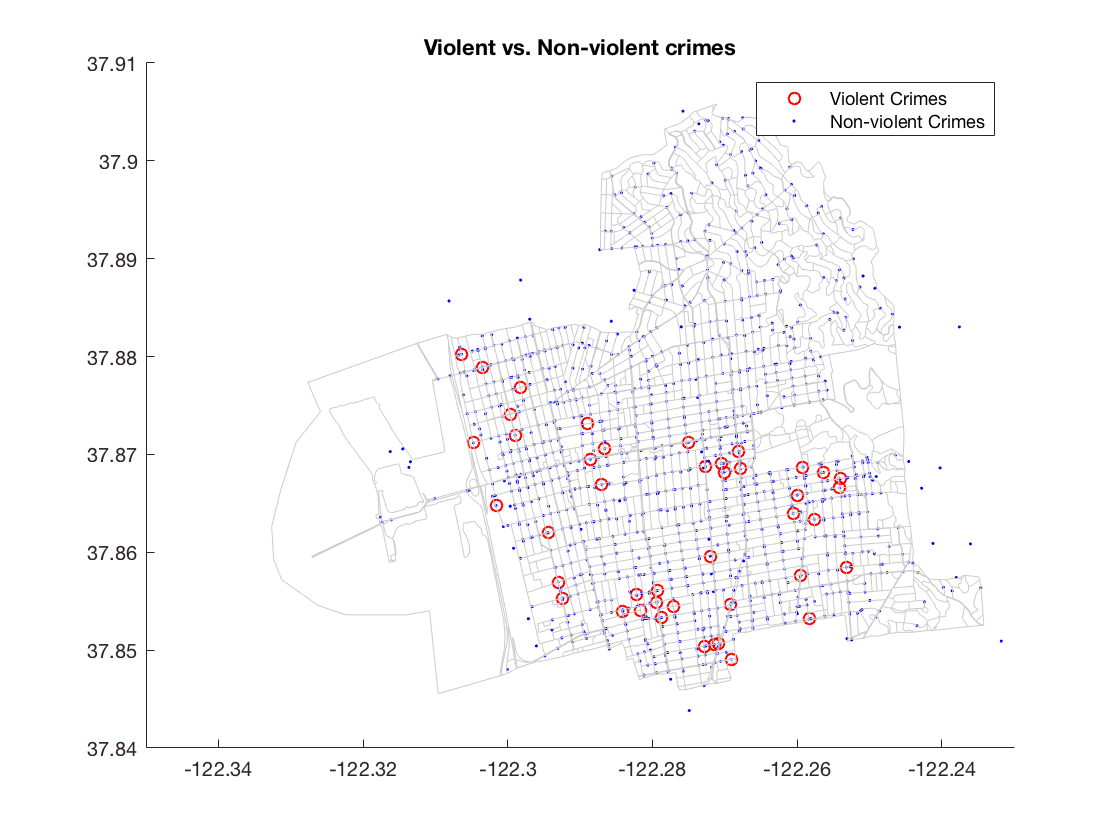

%Plotting the violent crimes versus the non-violent crimes
clf;
figure
hold on
plot(data.Longitude(data.VIOLENT_FLG == 1), data.Latitude(data.VIOLENT_FLG == 1), 'or',data.Longitude(data.VIOLENT_FLG == 0), data.Latitude(data.VIOLENT_FLG == 0),'.b')
title('Violent vs. Non-violent crimes')
legend('Violent Crimes','Non-violent Crimes')
saveas(gcf,'Violent crimes.png')
for x=1:size(S)
    plot(S(x).Lon, S(x).Lat,'Color',[0.8,0.8,0.8]);
end
axis([-122.35 -122.23 37.84 37.91])

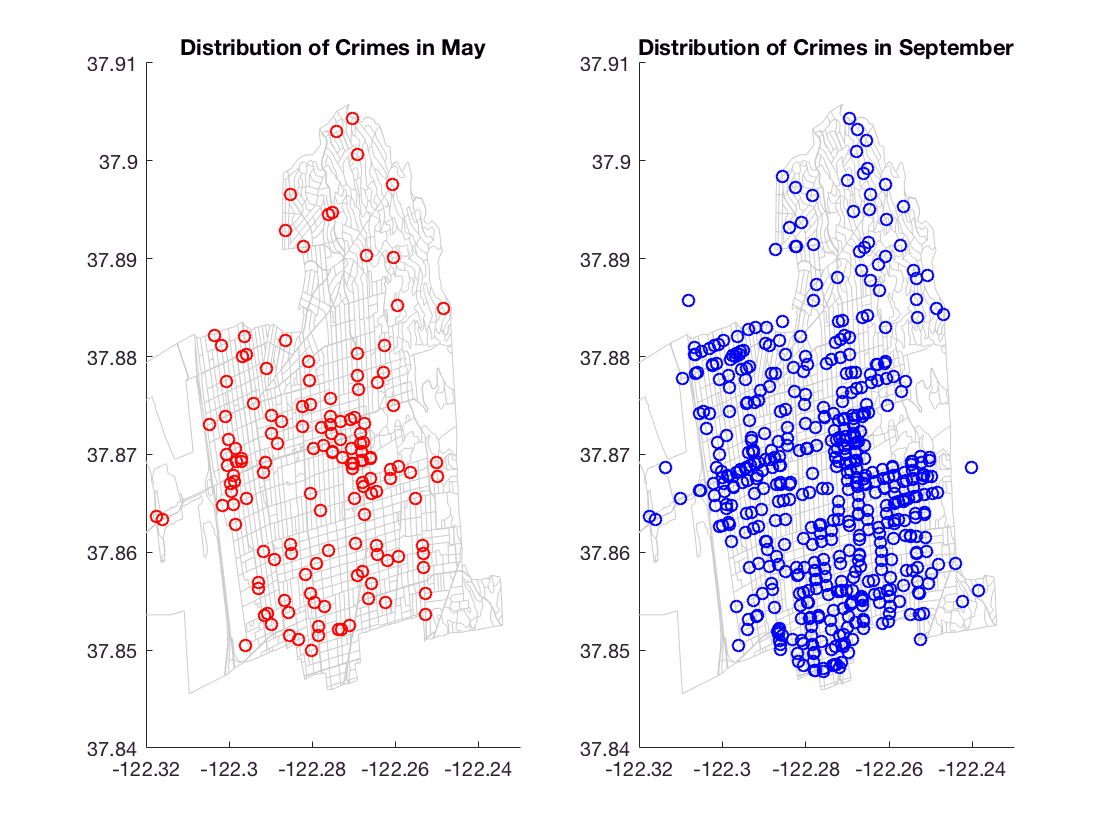

%Comparing the distributions of Berkeley crimes between two arbitrary months (May and September)

clf;
figure
subplot(1,2,1)
hold on
for x=1:size(S)
    plot(S(x).Lon, S(x).Lat,'Color',[0.8,0.8,0.8]);
end
plot(data.Longitude(data.EVENT_MONTH == 5), data.Latitude(data.EVENT_MONTH == 5), 'or')
axis([-122.32 -122.23 37.84 37.91])
title('Distribution of Crimes in May')
subplot(1,2,2)
hold on
for x=1:size(S)
    plot(S(x).Lon, S(x).Lat,'Color',[0.8,0.8,0.8]);
end
plot(data.Longitude(data.EVENT_MONTH == 9), data.Latitude(data.EVENT_MONTH == 9), 'ob')
axis([-122.32 -122.23 37.84 37.91])
title('Distribution of Crimes in September')

length(data.Latitude(data.EVENT_MONTH == 5))

sprintf('Number of crimes in May: %d', length(data.Latitude(data.EVENT_MONTH == 5)))

ans = Number of crimes in May: 167

sprintf('Number of violent crimes in May: %d', length(data.Latitude(data.EVENT_MONTH == 5 & data.VIOLENT_FLG == 1)))

ans = Number of violent crimes in May: 2

sprintf('Number of crimes in September: %d', length(data.Latitude(data.EVENT_MONTH == 9)))

ans = Number of crimes in September: 907

sprintf('Number of violent crimes in September: %d', length(data.Latitude(data.EVENT_MONTH == 9 & data.VIOLENT_FLG == 1)))

ans = Number of violent crimes in September: 7

This shows that September had a larger number of crimes in general as well as violent crimes than May. This analysis can be replicated for different months.

# Part 2 - Main Analysis

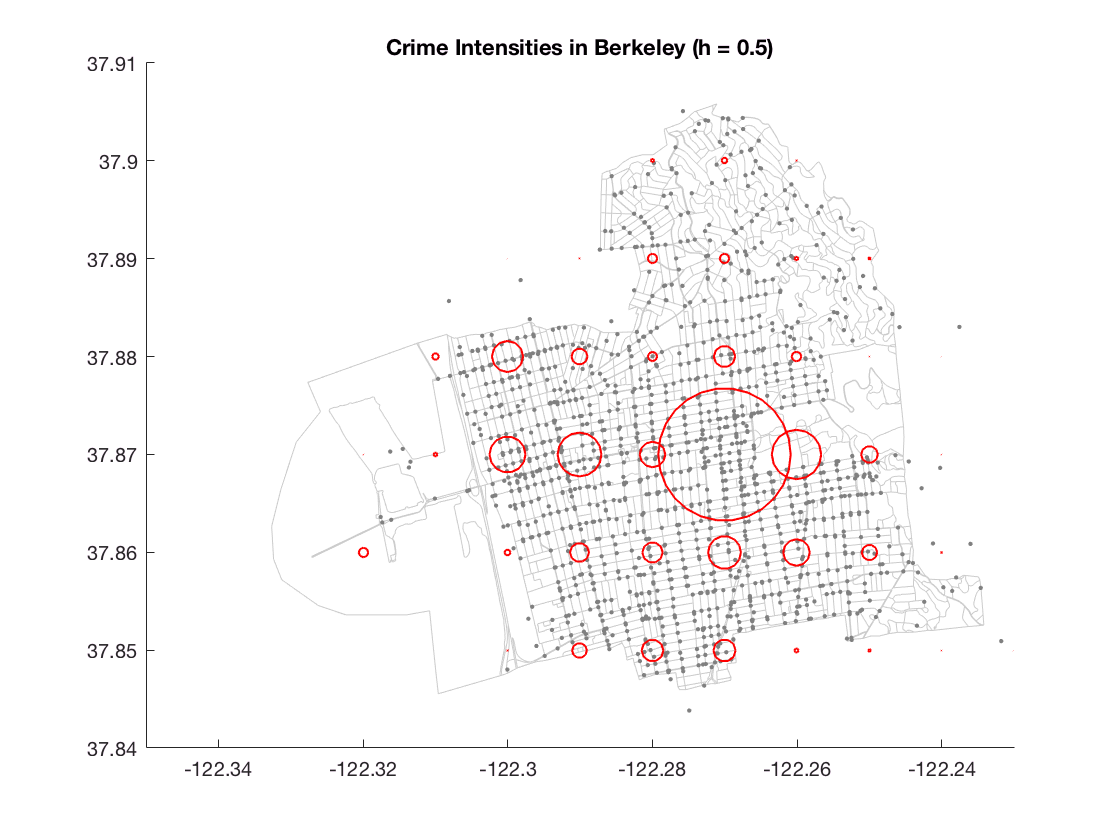

%Creating Intensity Maps based on number of crimes in Berkeley
h = 0.5; %Radius of observation
clf;
figure
hold on

for x=1:size(S)
    plot(S(x).Lon, S(x).Lat,'Color',[0.8,0.8,0.8]);
end
axis([-122.35 -122.23 37.84 37.91])

%Superimposing the Berkeley crimes onto the Berkeley shapefile
plot(data.Longitude, data.Latitude,'.','Color',[0.5,0.5,0.5],'MarkerSize',10)

for x = -122.32:0.01:-122.23
    for y = 37.84:0.01:37.91
        dist_to_event_j = 111.1*sqrt((x - data.Longitude).^2 + (y - data.Latitude).^2);
        lambda = length(dist_to_event_j(dist_to_event_j < h));
        if lambda > 0
            plot(x,y,'or', 'MarkerSize', 0.1*lambda);
        end
    end
end
title('Crime Intensities in Berkeley (h = 0.5)')
saveas(gcf,'Crime Intensities.png')

%Analysing patterns in distribution of berkeley crimes around the three BART Stations
berkeley_barts = readtable('Bart Stations.csv');
berkeley_barts

berkeley_barts =            Name             Lat        Lon  
    ___________________    ______    _______

    'North Berkeley'       37.874    -122.28
    'Downtown Berkeley'     37.87    -122.27
    'Ashby'                37.853    -122.27


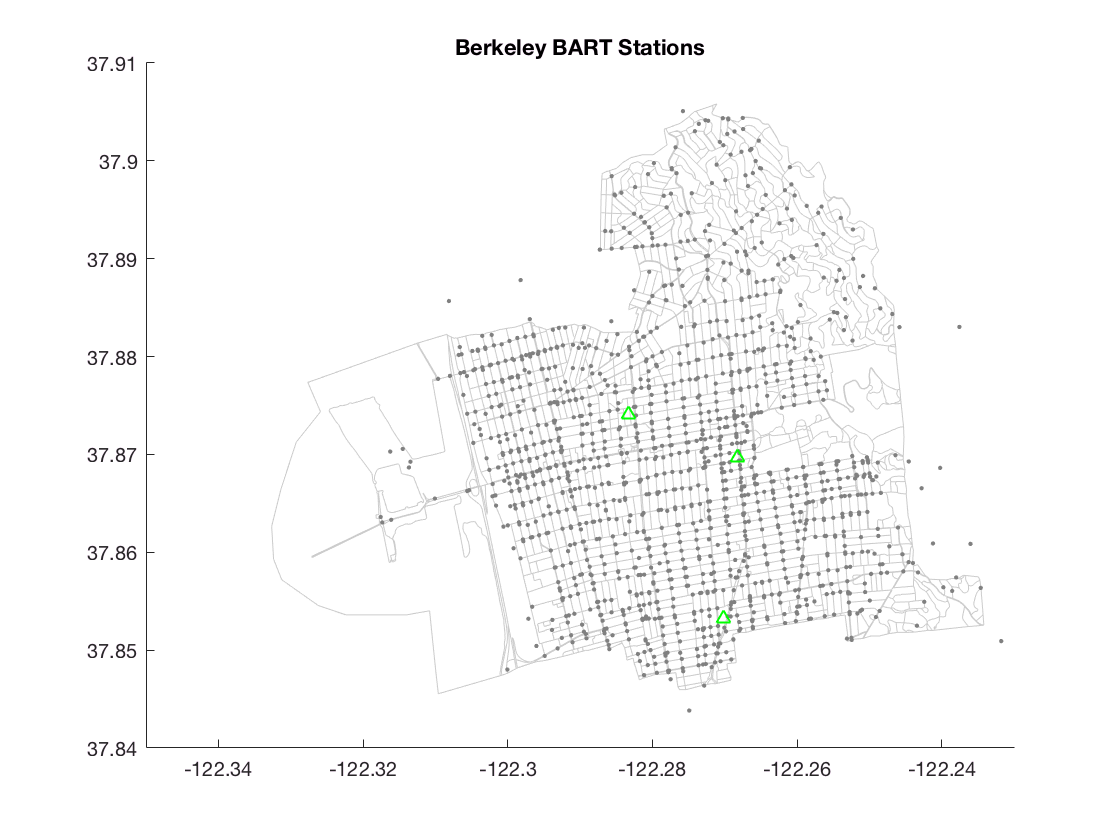

clf;
figure
hold on

%Plotting the Berkeley shape file
for x=1:size(S)
    plot(S(x).Lon, S(x).Lat,'Color',[0.8,0.8,0.8]);
end
axis([-122.35 -122.23 37.84 37.91])

%Superimposing the Berkeley crimes onto the Berkeley shapefile
plot(data.Longitude, data.Latitude,'.','Color',[0.5,0.5,0.5],'MarkerSize',10)

plot(berkeley_barts.Lon,berkeley_barts.Lat,'^g')
title('Berkeley BART Stations')

%Calculating crime intensity around BART Stations by creating buffers
for i=1:3
    [buffer_lat, buffer_lon] = bufferm(berkeley_barts.Lat(i), berkeley_barts.Lon(i), 0.005);
    island_buffer_struct = struct('lat', buffer_lat, 'lon', buffer_lon);
    plot(island_buffer_struct.lon, island_buffer_struct.lat)
    
    data_lon = data.Longitude;
    data_lat = data.Latitude;
    inside = inpolygon(data_lon,data_lat,buffer_lon,buffer_lat);
    data_lon(inside == false) = NaN;
    data_lat(inside == false) = NaN;
    
    length(inside(inside==1))
    crime_intensity = length(inside(inside==1))/(pi*0.3^2)
    
    data_lon(isnan(data_lon)) = [];
    data_lat(isnan(data_lat)) = [];
    simulated_events = struct('lon',data_lon,'lat',data_lat);
    plot(simulated_events.lon, simulated_events.lat, '.','MarkerSize',15)
end

ans = 156

crime_intensity = 551.7371

ans = 766

crime_intensity = 2.7092e+03

ans = 250

crime_intensity = 884.1941

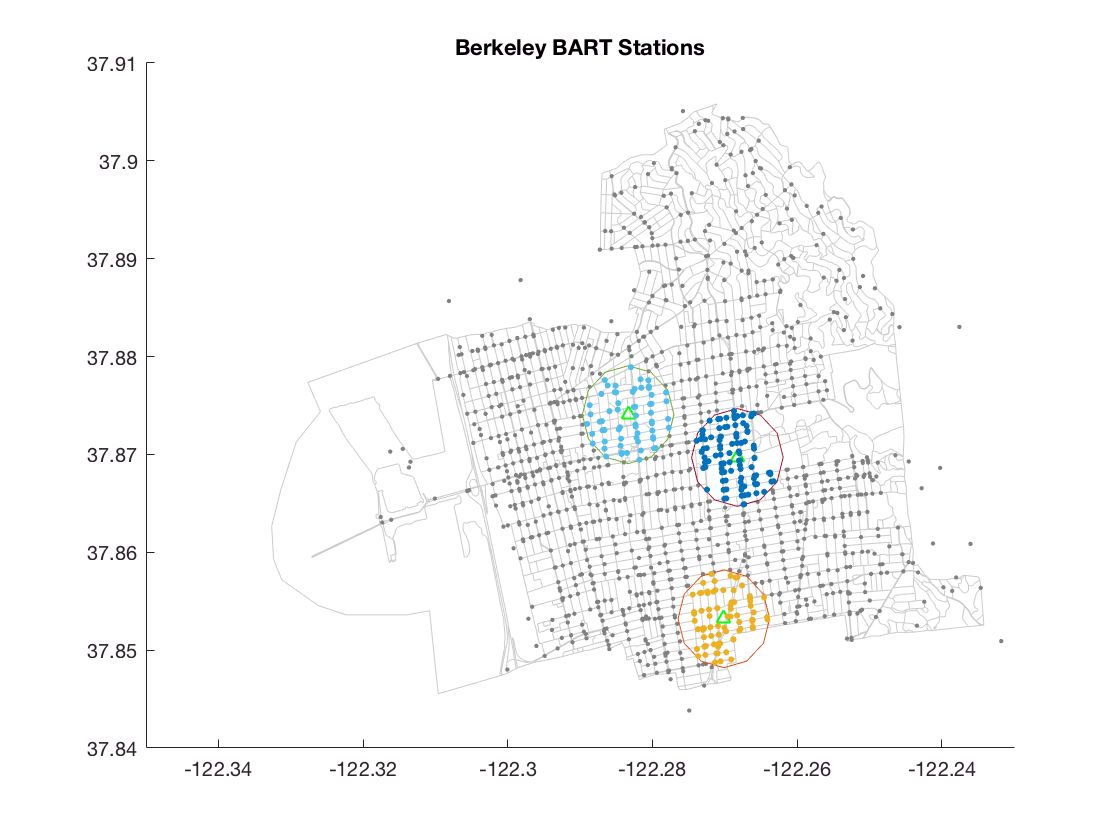

saveas(gcf,'bart with buffers.png')

# Part 3 - Recommendation

%Calculating the optimal location of a police station in Berkeley using distance optimality
min_distance = inf;

for x = -122.32:0.001:-122.23
    for y = 37.84:0.001:37.91
        dist_to_event_j = 111.1*sqrt((x - data.Longitude).^2 + (y - data.Latitude).^2);
        total_dist = sum(dist_to_event_j);
        %Getting the grid point with the minimum average distance to all crimes
        if total_dist <min_distance
            min_distance = total_dist;
            best_lon = x;
            best_lat = y;
        end
    end
end
best_lon

best_lon = -122.2730

best_lat

best_lat = 37.8680

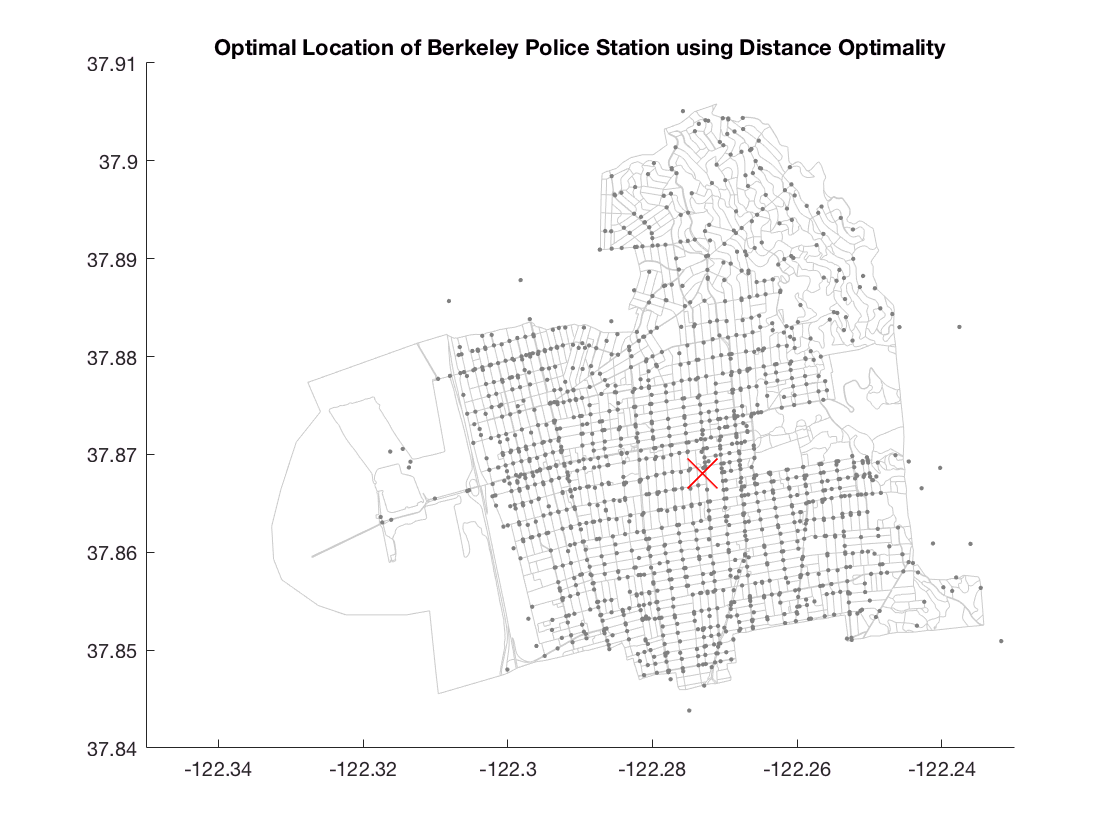

clf;
figure
hold on

%Plotting the Berkeley shape file
for x=1:size(S)
    plot(S(x).Lon, S(x).Lat,'Color',[0.8,0.8,0.8]);
end
axis([-122.35 -122.23 37.84 37.91])

%Superimposing the Berkeley crimes onto the Berkeley shapefile
plot(data.Longitude, data.Latitude,'.','Color',[0.5,0.5,0.5],'MarkerSize',10)

plot(best_lon,best_lat,'xr','MarkerSize',20)
title('Optimal Location of Berkeley Police Station using Distance Optimality')
saveas(gcf,'Optimal Police Station.png')

%Accounting for the safety of school children while calculating the optimal Berkeley Police Station location by looking at School locations
berkeley_schools = readtable('Berkeley_Schools - Sheet1 copy.csv'); %Manually chosen the four most risk prone schools based on crime intensity
berkeley_schools

berkeley_schools =                  Name                  Lat        Lng  
    ______________________________    ______    _______

    'Willard Middle School'           37.859    -122.26
    'Black Pine Circle Day School'    37.867    -122.29
    'Malcolm X Elementary'            37.854    -122.28
    'Longfellow Middle School'        37.859    -122.28


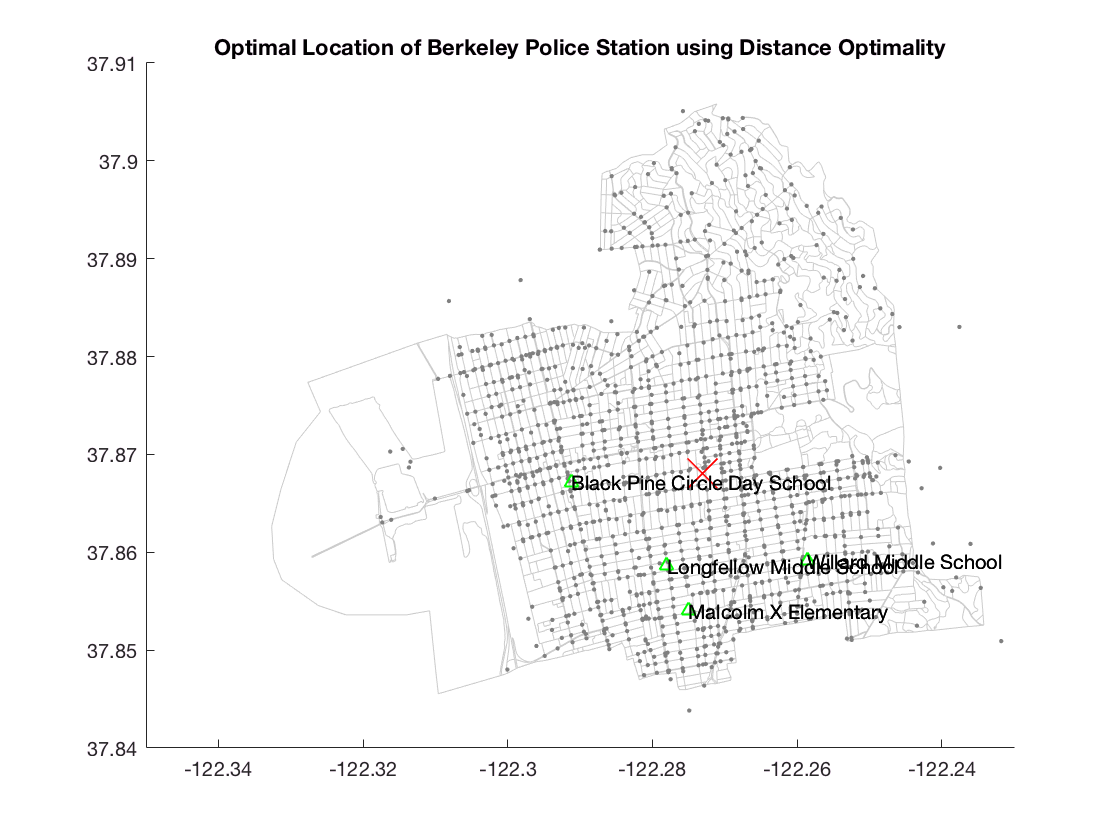

plot(berkeley_schools.Lng,berkeley_schools.Lat,'^g')
text(berkeley_schools.Lng,berkeley_schools.Lat,berkeley_schools.Name)

clf;
figure
hold on

%Plotting the Berkeley shape file
for x=1:size(S)
    plot(S(x).Lon, S(x).Lat,'Color',[0.8,0.8,0.8]);
end
axis([-122.35 -122.23 37.84 37.91])

%Superimposing the Berkeley crimes onto the Berkeley shapefile
plot(data.Longitude, data.Latitude,'.','Color',[0.5,0.5,0.5],'MarkerSize',10)

plot(best_lon,best_lat,'xr','MarkerSize',20)

school_crimes_lon = [];
school_crimes_lat = [];
for i=1:4
    [buffer_lat, buffer_lon] = bufferm(berkeley_schools.Lat(i), berkeley_schools.Lng(i), 0.005);
    island_buffer_struct = struct('lat', buffer_lat, 'lon', buffer_lon);
    plot(island_buffer_struct.lon, island_buffer_struct.lat)
    
    data_lon = data.Longitude;
    data_lat = data.Latitude;
    inside = inpolygon(data_lon,data_lat,buffer_lon,buffer_lat);
    data_lon(inside == false) = NaN;
    data_lat(inside == false) = NaN;
    
    length(inside(inside==1))
    crime_intensity = length(inside(inside==1))/(pi*0.3^2)
    
    data_lon(isnan(data_lon)) = [];
    data_lat(isnan(data_lat)) = [];
    simulated_events = struct('lon',data_lon,'lat',data_lat);
    school_crimes_lon=[school_crimes_lon;simulated_events.lon];
    school_crimes_lat=[school_crimes_lat;simulated_events.lat];
    plot(simulated_events.lon, simulated_events.lat, '.','MarkerSize',15)
end

ans = 226

crime_intensity = 799.3115

ans = 285

crime_intensity = 1.0080e+03

ans = 255

crime_intensity = 901.8780

ans = 177

crime_intensity = 626.0094

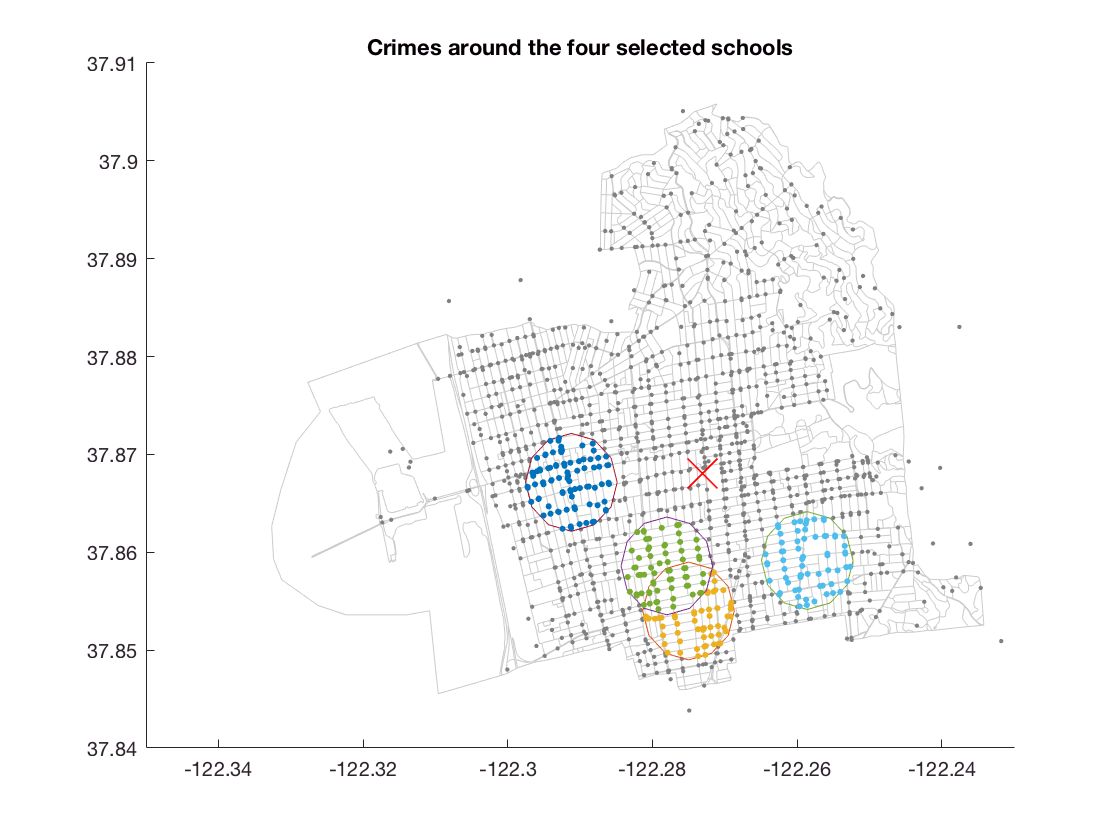

title('Crimes around the four selected schools')
saveas(gcf,'schools with buffers.png')

%Prioritizing crimes around the four schools by assigning them larger weight than other crimes

min_distance = inf;
min_school_distance = inf;
for x = -122.32:0.001:-122.23
    for y = 37.84:0.001:37.91
        dist_to_event_j = 111.1*sqrt((x - data.Longitude).^2 + (y - data.Latitude).^2); 
        dist_to_school_crime = 111.1*sqrt((x - school_crimes_lon).^2 + (y - school_crimes_lat).^2);
        %Appending the distance to school crimes array 5 times more than the distance to other crimes array 
        dist_to_event_j = vertcat(dist_to_event_j,dist_to_school_crime,dist_to_school_crime,dist_to_school_crime,dist_to_school_crime);
        
        total_dist = sum(dist_to_event_j);
        
        if total_dist <min_distance
            min_distance = total_dist;
            best_lon = x;
            best_lat = y;
        end
        
    end
end

best_lat

best_lat = 37.8620

best_lon

best_lon = -122.2760

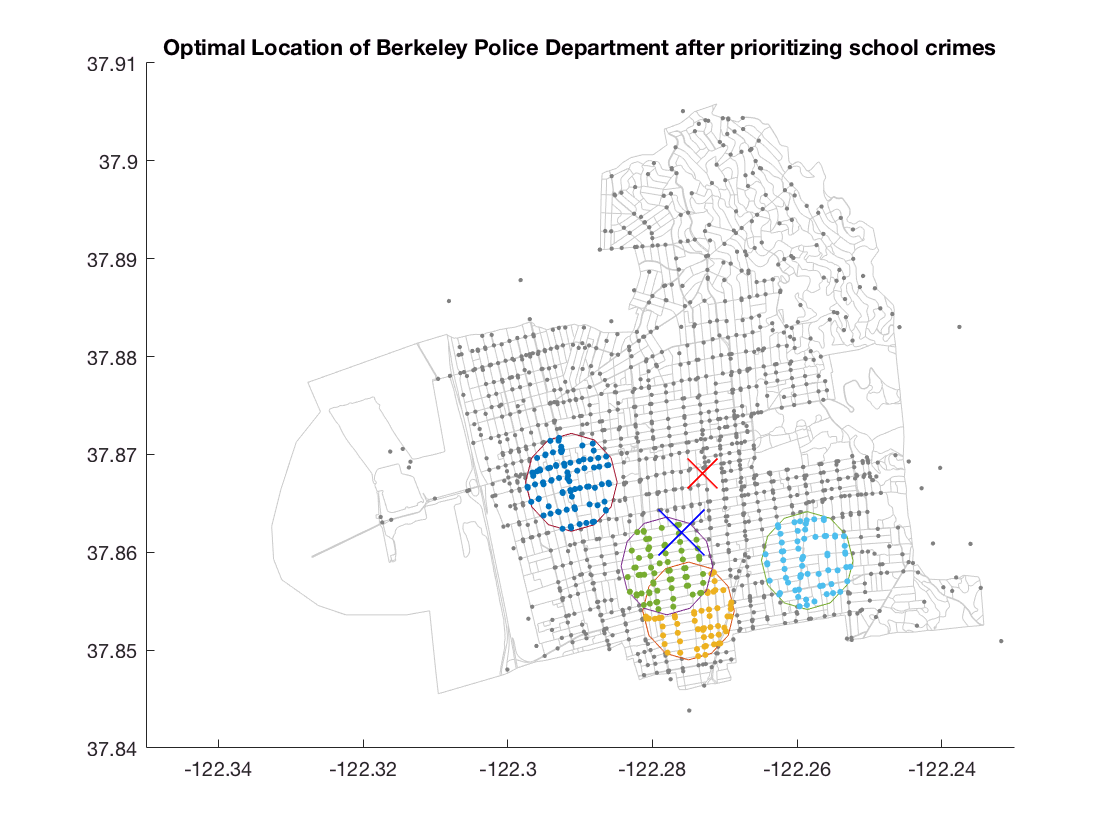


plot(best_lon,best_lat, 'xb','MarkerSize',30)
title('Optimal Location of Berkeley Police Department after prioritizing school crimes')
saveas(gcf,'final.png')